clearvars; close('all');
% GNSS headng
% compass = 'GNSS';

% load("data\CS_GNSS.mat");region='Celtic Sea';
% load("data\RT_GNSS.mat"); region='Rockall Trough';

% sig compasss
compass = 'signature';
% load("data\CS_SIG.mat"); region='Celtic Sea';
load("data\RT_SIG.mat");region='Rockall Trough';

% % sig compasss
% compass = 'bottomtrack';
% load("data\IN_BT.mat"); region='Inshore';
% load("data\RT_SIG.mat");region='Rockall Trough';


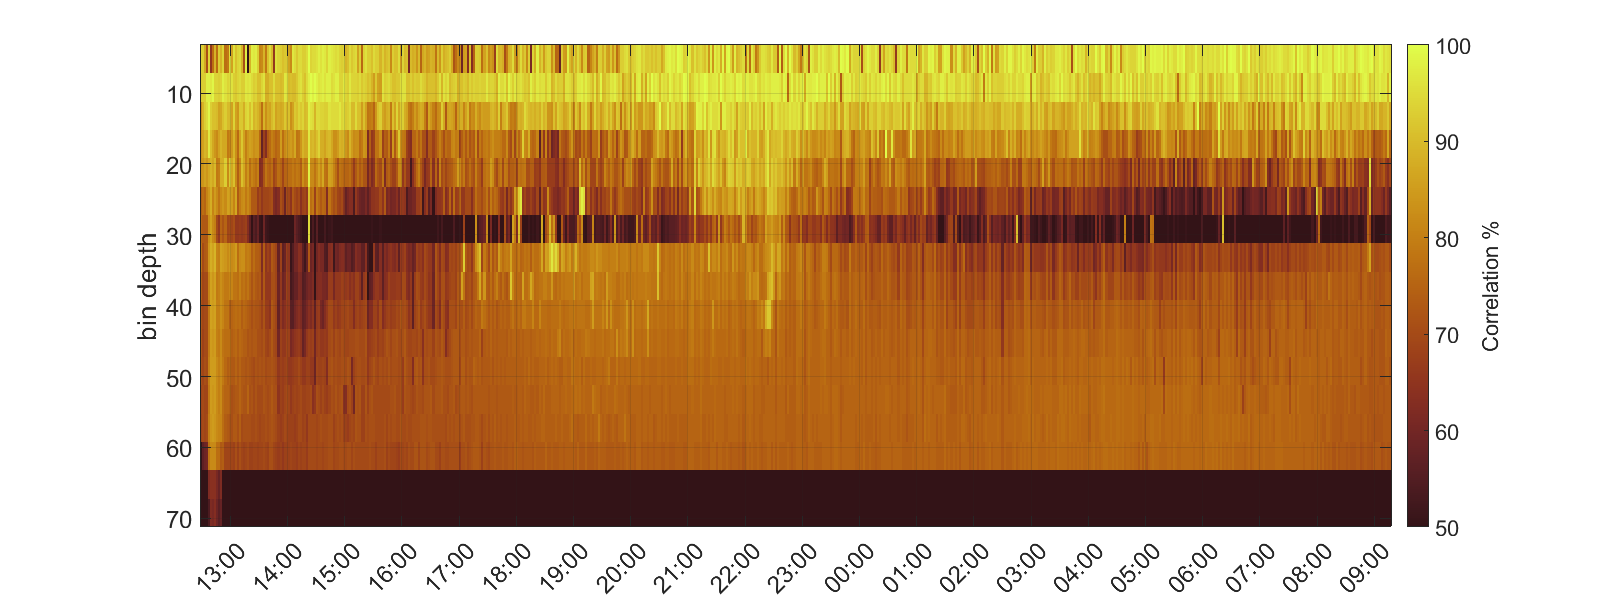


for ii = 1:numel(WatStruct)
       if ii==1
           x=NavStruct(ii).timestamp;
           y=WatStruct(ii).binDepth(:,1);
           z=WatStruct(ii).correlation(:,:,1);
           p=SensStruct(ii).pitch_deg;
       else
           x=[x NavStruct(ii).timestamp];
           z=[z WatStruct(ii).correlation(:,:,1)];
           p=[p;SensStruct(ii).pitch_deg ];
       end
end

figure('Renderer', 'painters', 'Position', [10 20 1600 600])
z(z==255)=NaN;
h=imagesc(x,y,z);
xlabel('');
ylabel('bin depth');
c=colorbar;
caxis([50 100]);
ylabel(c,'Correlation %');
cmocean('Solar');
axis ij; grid on;
datetick('x','HH:MM','keeplimits');
xtickangle(45)
set(gca,'FontSize',18);
print(gcf,'-dpng',['figures/' region '_correlation_' compass]) ;

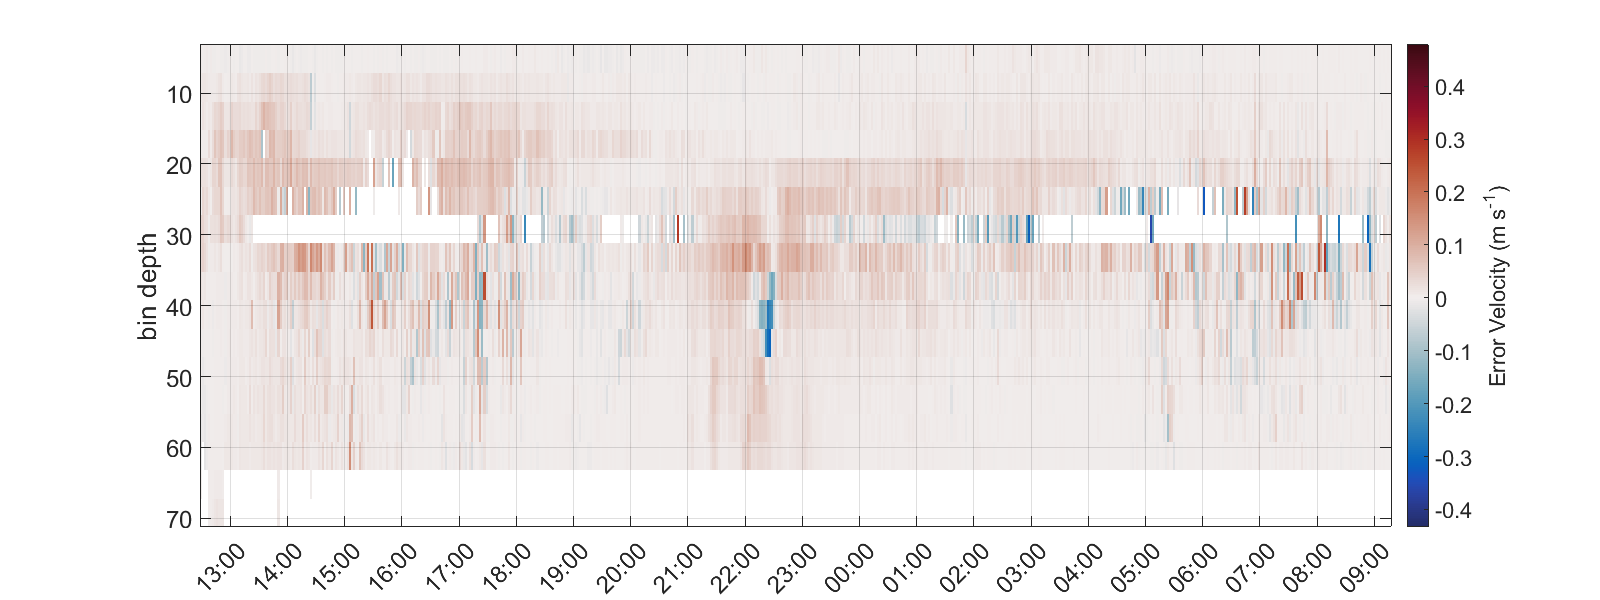




for ii = 1:numel(WatStruct)
       if ii==1
           x=NavStruct(ii).timestamp;
           y=WatStruct(ii).binDepth(:,1);
           z=WatStruct(ii).vError_ms;
           p=SensStruct(ii).pitch_deg;
       else
           x=[x NavStruct(ii).timestamp];
           z=[z WatStruct(ii).vError_ms];
           p=[p;SensStruct(ii).pitch_deg ];
       end
end

figure('Renderer', 'painters', 'Position', [10 20 1600 600])
h=imagesc(x,y,z);
set(h, 'AlphaData', ~isnan(z))
xlabel('');
ylabel('bin depth');
c=colorbar;
ylabel(c,'Error Velocity (m s^{-1})');
cmocean('balance','pivot',0);
axis ij; grid on;
datetick('x','HH:MM','keeplimits');
xtickangle(45)
set(gca,'FontSize',18);
print(gcf,'-dpng',['figures/' region '_verror_' compass]) ;